# 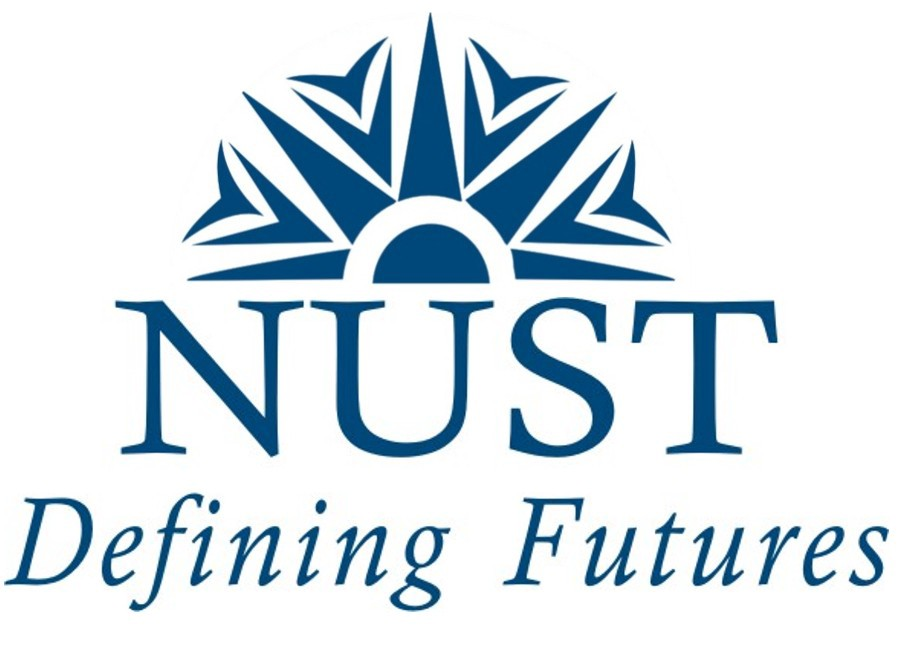

# ASSIGNMENT 1

*Instructor: Dr Rizwan Ahmad*

*Prepared by: Ali Hassan*

***Author: Mahnoor Anjum***

***Registration Number: 00000330720***

***Class: MSEE-TCN-2K20***

## **Question No 1**

Consider a binary symmetric channel used for communication.  A transmitter (B) wishes to send a message (a B1 or a B2), and the receiver (A) received a message. It is assumed that the bit is usually transmitted correctly, but it will be "flipped" with a small probability (the "crossover probability"). A receiver received the information and decode the message after decoding. The receiver send this message back to the transmitter

- Calculate P(A1) and P(A2).

- Calculate the crossover probability when receiver send back to message to transmitter.

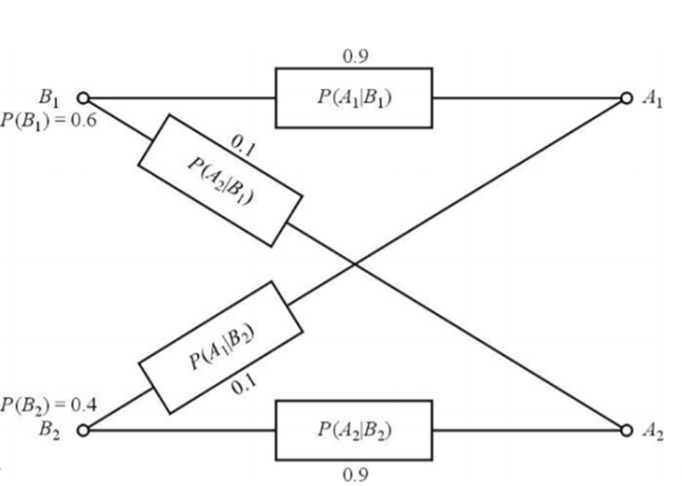

P_B1 = 0.6; %prior probability of B1
P_B2 = 0.4; %prior probability of B2
P_A1_B1 = 0.9; %likelihood of A1 given B1 
P_A2_B1 = 0.1; %likelihood of A2 given B1
P_A1_B2 = 0.1; %likelihood of A1 given B2
P_A2_B2 = 0.9; %likelihood of A2 given B2

% By the law of total probability
% P_A1 = P(A1 intersection B1) + P(A1 intersection B2)
P_A1 = (P_A1_B1 * P_B1) + (P_A1_B2 * P_B2)

P_A1 = 0.5800


P_A2 = (P_A2_B1 * P_B1) + (P_A2_B2 * P_B2)

P_A2 = 0.4200

P_B2_A1 = (P_A1_B2 * P_B2) / P_A1

P_B2_A1 = 0.0690

P_B1_A2 = (P_A2_B1 * P_B1) / P_A2

P_B1_A2 = 0.1429

Crossover probability = P(B1 | A2) + P(B2 | A1) 

crossover = P_B1_A2 + P_B2_A1

crossover = 0.2118

## **Question No 2**

Consider a system that randomly assign a variable X={1,2,3} with uniform probability, to a variable Y={1,2,3}. The conditional probability assignments are shown in the figure. Compute the following:

- If the event y=3 was observed. What is the probability that it is coming from = 3.

- Compute the expected value of Y.

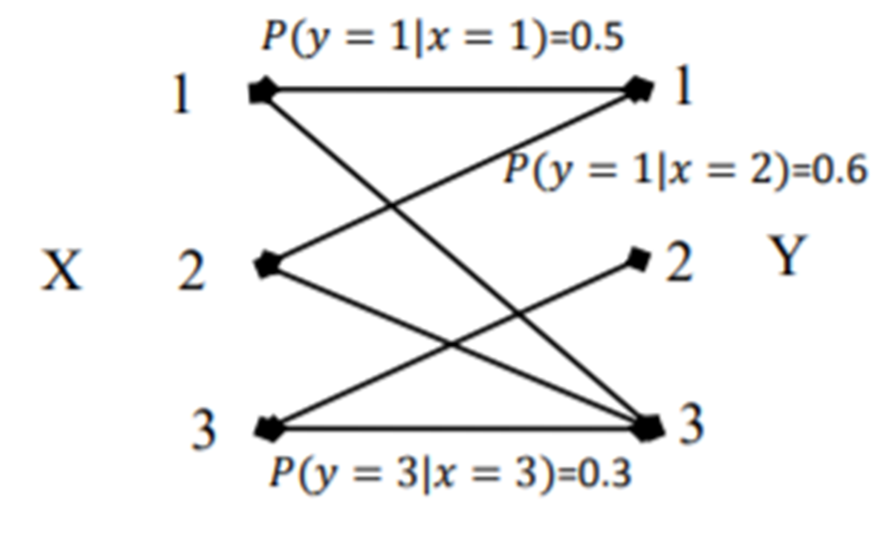

P_X = [1/3 1/3 1/3]; 
Y = [1 2 3];



% by the axioms of probability 
% X1 Connects to Y1 and Y3  
P_Y1_X1 = 0.5;
P_Y3_X1 = 1 - P_Y1_X1

P_Y3_X1 = 0.5000


% X2 Connects to Y1 and Y3  
P_Y1_X2 = 0.6;
P_Y3_X2 = 1 - P_Y1_X2

P_Y3_X2 = 0.4000


% X3 Connects to Y3 and Y2  
P_Y3_X3 = 0.3;
P_Y2_X3 = 1 - P_Y3_X3

P_Y2_X3 = 0.7000

% Y1 has X1 X2
P_Y1 = P_Y1_X2*P_X(2) + P_Y1_X1*P_X(1)

P_Y1 = 0.3667

% Y2 has X3
P_Y2 = P_Y2_X3*P_X(3) 

P_Y2 = 0.2333

% Y3 has X1 X2 X3
P_Y3 = P_Y3_X2*P_X(2) + P_Y3_X1*P_X(1)+ P_Y3_X3*P_X(3)

P_Y3 = 0.4000


% If Y3 is observed, Pr that it comes from X3 is
P_X3_Y3 = (P_Y3_X3 * P_X(3))/P_Y3

P_X3_Y3 = 0.2500

P_Y = [P_Y1 P_Y2 P_Y3];
expected_value_Y = sum(Y.*P_Y)

expected_value_Y = 2.0333

## **Question No 3**

The probability mass function of X is

                        X1                      p(x1)

                        0                      0.005

                        1                      0.022

                        2                      0.244

                        3                      0.729

             The cumulative distribution function of X is

                        X2                      F(x2)

                        0                      0.001

                        1                      0.028

                        2                      0.271

                        3                      1.000

Plot Cdf and Pdf of the data points.

Calculate mean and variance of these data points. 

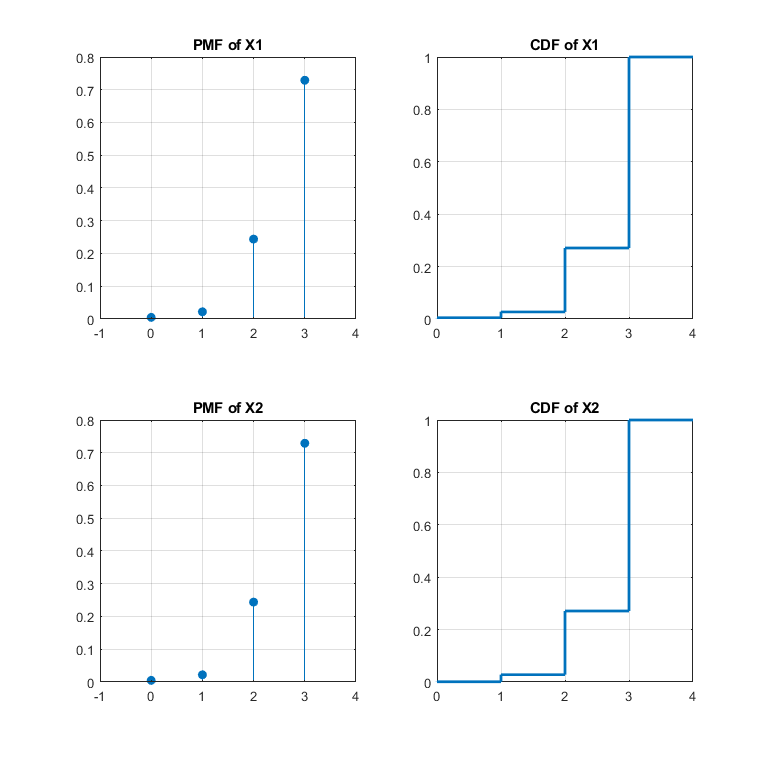

X1 = [0 1 2 3];
X2 = [0 1 2 3];
pmfX1 = [0.005 0.022 0.244 0.729];
cdfX1 = [pmfX1(1) pmfX1(1)+pmfX1(2) pmfX1(1)+pmfX1(2)+pmfX1(3) ...
            pmfX1(1)+pmfX1(2)+pmfX1(3)+pmfX1(4)];
cdfX2 = [0.001 0.028 0.271 1.000];
pmfX2 = [cdfX2(1) cdfX2(2)-cdfX2(1) cdfX2(3)-cdfX2(2) cdfX2(4)-cdfX2(3)];
clf;
set(gcf, 'Position',  [100, 100, 800, 800])
subplot(221), stem(X1, pmfX1, "filled"), xlim([-1 4]), grid on, title("PMF of X1"); 
subplot(222), hold on, hold on, grid on, box on, title("CDF of X1");

prev = 0;
for i = 1:length(X1)
    line([X1(i) X1(i)], [prev cdfX2(i)], 'LineWidth', 2);
    line([X1(i) X1(i)+1], [cdfX1(i) cdfX1(i)], 'LineWidth', 2);
    prev = cdfX1(i);
end
subplot(223), stem(X2, pmfX1, "filled"), xlim([-1 4]), grid on, title("PMF of X2"); 
subplot(224), hold on, grid on, box on,  title("CDF of X2");
prev = 0;
for i = 1:length(X2)
    line([X2(i) X2(i)], [prev cdfX2(i)], 'LineWidth', 2);
    line([X2(i) X2(i)+1], [cdfX2(i) cdfX2(i)], 'LineWidth', 2);
    prev = cdfX2(i);
end

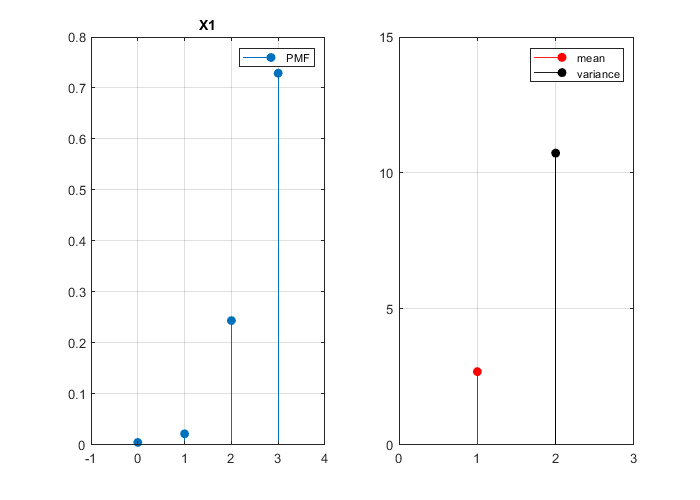

meanX1 = sum(X1.*pmfX1);
varX1  = sum((X1 - meanX1).^2);
meanX2 = sum(X2.*pmfX2);
varX2  = sum((X2 - meanX2).^2);
% Use Q3_Plotter here
Q3_Plotter(X1, pmfX1, 'X1')

***Variance X1  = 10.731***

***Mean X1 = 2.697***

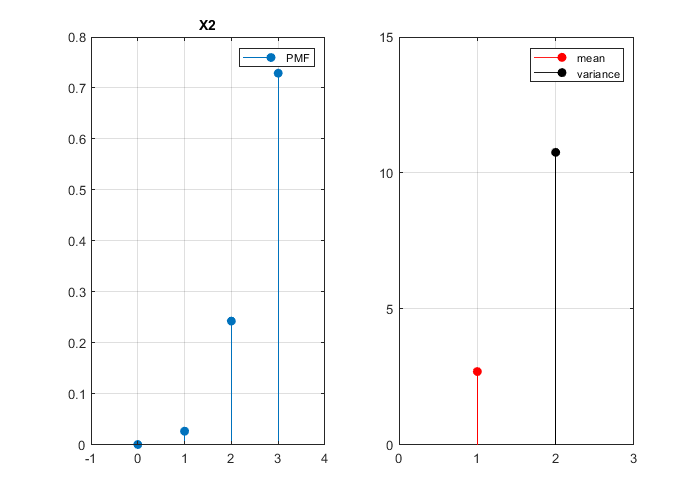

Q3_Plotter(X2, pmfX2, 'X2')

***Variance X2  = 10.760***

***Mean X2 = 2.700***

## **Question No 4**

Assume we want to transmit the following binary string: 101011001101011100001111. Use assumptions where required. Show the resulting signal waveform using the following line coding techniques: 

•          Unipolar NRZ 

•          Unipolar RZ 

•          Manchester NRZ

•          Differential Manchester

•          Bipolar Alternate Mark Inversion 

•          Pseudo ternary

•          B8ZS

•          HDB3

•          2B1Q

•          8B6T

•          4D-PAM5

•          MLT-3

## Unipolar NRZ 

str = '101011001101011100001111';
L   = length(str);
unipolarNRZ = '';
one = '1';
zero = '0';
% Unipolar NRZ 
for i=1:L
    if str(i) == '1'
        unipolarNRZ = [unipolarNRZ one];
    else
        unipolarNRZ = [unipolarNRZ zero];
    end
end
unipolarNRZ

unipolarNRZ = '101011001101011100001111'

Data              = 101011001101011100001111

UnipolarNRZ = 101011001101011100001111

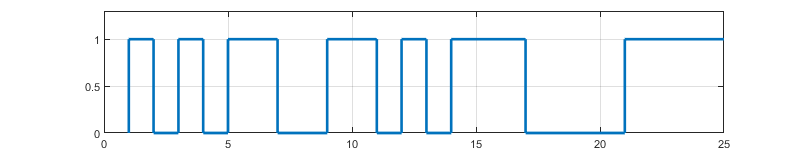

Q4_plotter_01(unipolarNRZ)

## Unipolar RZ

str = '101011001101011100001111';
L   = length(str);
unipolarRZ = '';
one = '10';
zero = '00';
% Unipolar RZ 
for i=1:L
    if str(i) == '1'
        unipolarRZ = [unipolarRZ one];
    else
        unipolarRZ = [unipolarRZ zero];
    end
end
unipolarRZ

unipolarRZ = '100010001010000010100010001010100000000010101010'

Data             = 101011001101011100001111

UnipolarRZ  = 100010001010000010100010001010100000000010101010

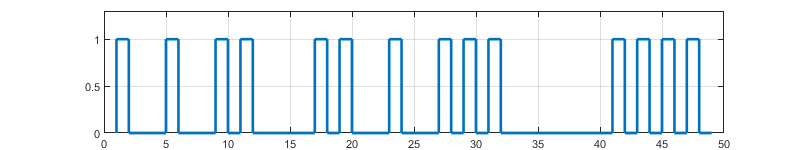

Q4_plotter_01(unipolarRZ)

## Manchester NRZ Thomas

str = '101011001101011100001111';
L   = length(str);
ManchesterNRZ = '';
one = '10';
zero = '01';
% Unipolar RZ 
for i=1:L
    if str(i) == '1'
        ManchesterNRZ = [ManchesterNRZ one];
    else
        ManchesterNRZ = [ManchesterNRZ zero];
    end
end
ManchesterNRZ

ManchesterNRZ = '100110011010010110100110011010100101010110101010'

Data             = 101011001101011100001111

ManchesterNRZ  = 100110011010010110100110011010100101010110101010

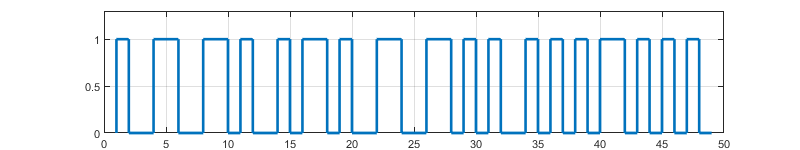

Q4_plotter_01(ManchesterNRZ)

## Manchester NRZ IEEE

str = '101011001101011100001111';
L   = length(str);
ManchesterNRZ = '';
one = '01';
zero = '10';
% Unipolar RZ 
for i=1:L
    if str(i) == '1'
        ManchesterNRZ = [ManchesterNRZ one];
    else
        ManchesterNRZ = [ManchesterNRZ zero];
    end
end
ManchesterNRZ

ManchesterNRZ = '011001100101101001011001100101011010101001010101'

Data             = 101011001101011100001111

ManchesterNRZ  = 011001100101101001011001100101011010101001010101

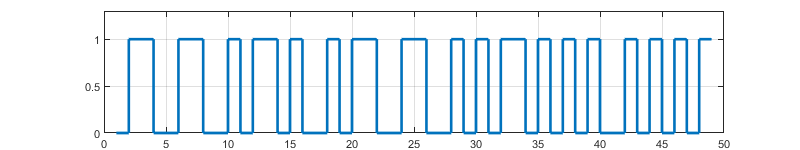

Q4_plotter_01(ManchesterNRZ)

## Differential Manchester

str = '101011001101011100001111';
L   = length(str);
diffManchester = '0';
one = '01';
zero = '10';
% Unipolar RZ 
for i=1:L
    if diffManchester(end) == '1'
        if str(i) == '0'
           diffManchester = [diffManchester '01'];
        else
           diffManchester = [diffManchester '10'];
        end
    else
        if str(i) == '0'
           diffManchester = [diffManchester '10'];
        else
           diffManchester = [diffManchester '01'];
        end
    end
end
diffManchester(2:end)

ans = '010110100110101001101001011001101010101001100110'

Data             = 101011001101011100001111

diffManchester  = 010110100110101001101001011001101010101001100110

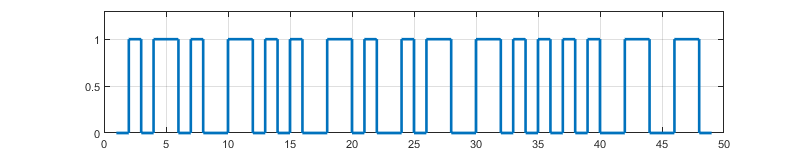

Q4_plotter_01(diffManchester(2:end))

## Bipolar Alternate Mark Inversion 

str = '101011001101011100001111';
L   = length(str);
BAMI = '';
one = '+';
zero = '0';

for i=1:L
    if str(i) == '1'
        BAMI = [BAMI one]; 
        if one == '+'
            one = '-';
        else
            one = '+';
        end
    else
        BAMI = [BAMI zero];
    end
end
BAMI

BAMI = '+0-0+-00+-0+0-+-0000+-+-'

Data             = 101011001101011100001111

BAMI            = +0-0+-00+-0+0-+-0000+-+-

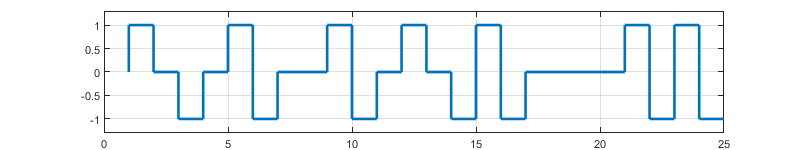

Q4_plotter_PNZ(BAMI)

## Pseudo ternary

str = '101011001101011100001111';
L   = length(str);
PT = '';
one = '0';
zero = '+';

for i=1:L
    if str(i) == '0'
        PT = [PT zero]; 
        if zero == '+'
            zero = '-';
        else
            zero = '+';
        end
    else
        PT = [PT one];
    end
end
PT

PT = '0+0-00+-00+0-000+-+-0000'

Data             = 101011001101011100001111

PT                = 0+0-00+-00+0-000+-+-0000

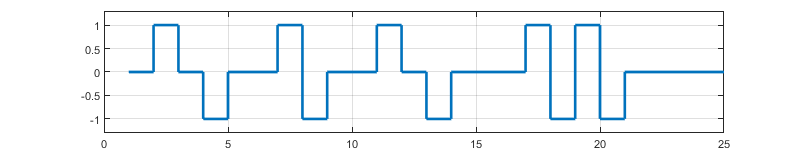

Q4_plotter_PNZ(PT)

## B8ZS

str = '101011001101011100001111';
L   = length(str);
B8ZS = '';
one = 'b';
zero = '0';
for i=1:L
    if str(i) == '1'
        B8ZS = [B8ZS one]; 
    else
        B8ZS = [B8ZS zero];
    end
end

idxs = strfind(B8ZS, '00000000'); 
while ~isempty(idxs)
    idx = idxs(1);
    B8ZS(idx:idx+7) = '000vb0vb';
    idxs = strfind(B8ZS, '00000000'); 
end

B8ZS = helper(B8ZS)

B8ZS = '+0-0+-00+-0+0-+-0000+-+-'

Data             = 101011001101011100001111

B8ZS            = +0-0+-00+-0+0-+-0000+-+-

Q4_plotter_PNZ(B8ZS)

## HDB3

str = '101011001101011100001111';
L   = length(str);
HDB3 = '';
one = 'b';
zero = '0';
for i=1:L
    if str(i) == '1'
        HDB3 = [HDB3 one]; 
    else
        HDB3 = [HDB3 zero];
    end
end

idxs = strfind(HDB3, '0000'); 
lastIdx = 1;
while ~isempty(idxs)
    idx = idxs(1);
    count = length(strfind(HDB3(lastIdx:idx), 'b'));
    if mod(count,2) == 0
        HDB3(idx:idx+3) = 'b00v';
        lastIdx = idx+3;
    else
        HDB3(idx:idx+3) = '000v';
        lastIdx = idx+3;
    end
    idxs = strfind(HDB3, '0000'); 
end

HDB3 = helper(HDB3)

HDB3 = '+0-0+-00+-0+0-+-+00+-+-+'

Data             = 101011001101011100001111

HDB3           =  +0-0+-00+-0+0-+-+00+-+-+

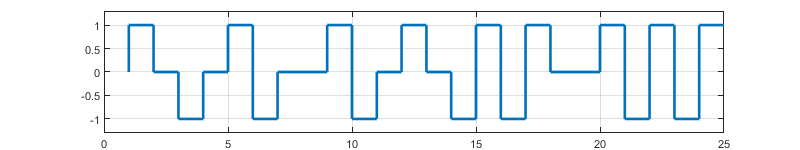

Q4_plotter_PNZ(HDB3)

## 2B1Q

% -3 -1 1 3 
%  1  2 3 4 
% 00 3 2
% 01 4 1
% 10 2 3
% 11 1 4
str = '101011001101011100001111';
e2B1Q = '4';
L = length(str);
t = 0;
for i=1:2:L-1
    if str(i:i+1) == '10'
        if (e2B1Q(end) == '4') || (e2B1Q(end) == '3')
            e2B1Q = [e2B1Q '2'];            
        else
            e2B1Q = [e2B1Q '3'];
        end
    elseif str(i:i+1) == '11'
        if (e2B1Q(end) == '4') || (e2B1Q(end) == '3')
            e2B1Q = [e2B1Q '1'];            
        else
            e2B1Q = [e2B1Q '4'];
        end
    elseif str(i:i+1) == '01'
        if (e2B1Q(end) == '4') || (e2B1Q(end) == '3')
            e2B1Q = [e2B1Q '4'];            
        else
            e2B1Q = [e2B1Q '1'];
        end
    else
        if (e2B1Q(end) == '4') || (e2B1Q(end) == '3')
            e2B1Q = [e2B1Q '3'];            
        else
            e2B1Q = [e2B1Q '2'];
        end
    end
end
e2B1Q(2:end)

ans = '231244412241'

Data             = 101011001101011100001111

2B1Q           =  231244412241 

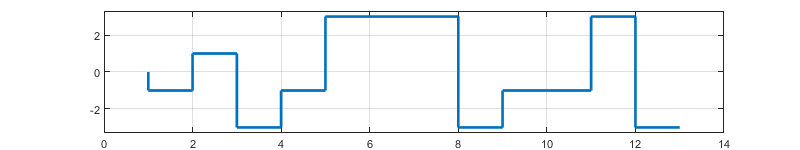

Q4_plotter_1234(e2B1Q(2:end))

## 8B6T

str = '101011001101011100001111';
e8B6T= '-++--+-0+++-+0--0+'

e8B6T = '-++--+-0+++-+0--0+'

Data             = 101011001101011100001111

8B6T           =  -++--+-0+++-+0--0+

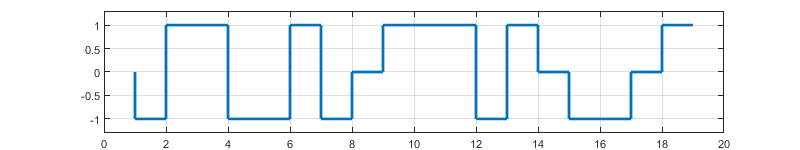

Q4_plotter_PNZ(e8B6T)

## 4D-PAM5

% -2 -1 1 2
% 1  2  3  4
% 00 3
% 01 4
% 10 2
% 11 1
str = '101011001101011100001111';
e4DPAM5 = '';
L = length(str);
t = 0;
for i=1:2:L-1
    if str(i:i+1) == '00'
        e4DPAM5 = [e4DPAM5 '3'];            
    elseif str(i:i+1) == '01'
        e4DPAM5 = [e4DPAM5 '4'];            
    elseif str(i:i+1) == '10'
        e4DPAM5 = [e4DPAM5 '2'];            
    else
        e4DPAM5 = [e4DPAM5 '1'];            
    end
end
e4DPAM5

e4DPAM5 = '221314413311'

Data             = 101011001101011100001111

4D-PAM5     = 221314413311

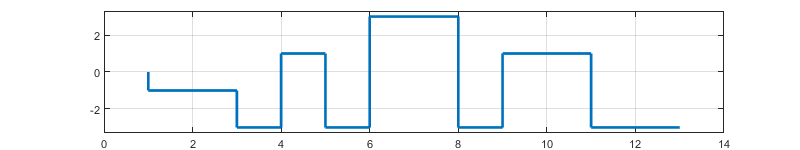


Q4_plotter_1234(e4DPAM5)

## MLT3

str    = '101011001101011100001111';
symbols = ['+', '0', '-', '0'];
symbol = rem(0, 4) + 1;
L = length(str);
MLT3 = '';
t = 0;
for i = 1:L
    if str(i) == '0'
        MLT3 = [MLT3 symbol];
    else
        t = t + 1;
        idx = rem(t-1, 4) + 1;
        symbol = symbols(idx);
        MLT3 = [MLT3 symbol];
    end
end

MLT3  

MLT3 = '++00-000+00--0+00000-0+0'

Data             = 101011001101011100001111

MLT-3           = ++00-000+00--0+00000-0+0

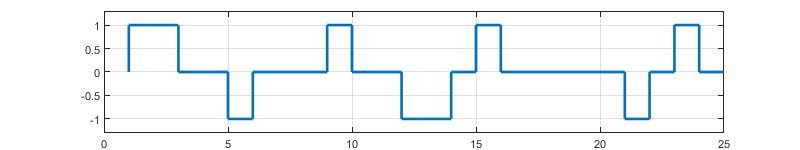

Q4_plotter_PNZ(MLT3)

## Helper Functions

function handle = Q3_Plotter(X, pmfX, str)
    clf;
    set(gcf, 'Position',  [100, 100, 700, 500])
    meanX = sum(X.*pmfX);
    varX  = sum((X - meanX).^2);
    subplot(121), stem(X, pmfX, "filled"), xlim([-1 4]), grid on, title(str), legend("PMF"); 
    subplot(122), hold on, xlim([0 3]), ylim([0 15]), grid on, box on;
    stem(1, meanX, 'r', "filled");
    stem(2, varX, 'k', "filled");
    legend("mean", "variance");
end

function handle = Q4_plotter_01(str)
    clf;
    code = str;
    L = length(code);
    figure(); ylim([0, 1.3]); 
    set(gcf, 'Position',  [100, 100, 800, 150])
    hold on; box on; grid on;prev = 0;
    for i=1:L
        if code(i) == '0'
            line([i, i+1], [0 0], 'LineWidth', 2);
            line([i, i], [prev 0], 'LineWidth', 2);
            prev = 0;
        else
            line([i, i+1], [1 1], 'LineWidth', 2);
        
            line([i, i], [prev 1], 'LineWidth', 2);
            prev = 1;
    
        end
    end
end

function handle = Q4_plotter_PNZ(str)
    clf;
    code = str;
    L = length(code);
    figure(); ylim([-1.3, 1.3]); 
    set(gcf, 'Position',  [100, 100, 800, 150])
    hold on; box on; grid on; prev = 0;
    for i=1:L
        if code(i) == '0'
            line([i, i+1], [0 0], 'LineWidth', 2);
            line([i, i], [prev 0], 'LineWidth', 2);
            prev = 0;
        elseif code(i)=="+"
            line([i, i+1], [1 1], 'LineWidth', 2);
            line([i, i], [prev 1], 'LineWidth', 2);
            prev = 1;
        else
            line([i, i+1], [-1 -1], 'LineWidth', 2);
            line([i, i], [prev -1], 'LineWidth', 2);
            prev = -1;
    
        end
    end
end

function handle = Q4_plotter_1234(str)
clf;
code = str;
L = length(code);
figure(); ylim([-3.3, 3.3]); 
set(gcf, 'Position',  [100, 100, 800, 150])
hold on; box on; grid on;
prev = 0;
for i=1:L
    if code(i) == '1'
        line([i, i], [prev -3], 'LineWidth', 2);
        line([i, i+1], [-3 -3], 'LineWidth', 2);
        prev = -3;
    elseif code(i)=="2"
        line([i, i], [prev -1], 'LineWidth', 2);
        line([i, i+1], [-1 -1], 'LineWidth', 2);
        prev = -1;
    elseif code(i) == "3"
        line([i, i], [prev 1], 'LineWidth', 2);
        line([i, i+1], [1 1], 'LineWidth', 2);
        prev = 1;
    else
        line([i, i], [prev 3], 'LineWidth', 2);
        line([i, i+1], [3 3], 'LineWidth', 2);
        prev = 3;
    end
end
end


function code = helper(str)
L = length(str);
code = '';
t = 0;
prev = '-';
for i = 1:L
    if (str(i) == '0')
        code = [code '0'];
    else
        if str(i) == 'v'
            code = [code prev];
        else
            if (prev == '-')
            code = [code '+'];
            prev = '+';
            else
                code = [code '-'];
                prev = '-';
            end
        end
    end
end
end